clear
close all
clc

准备参数，定义预变换矩阵

T = 2;
OMG = 100*pi;
N = 100;
[t,omg,FT,IFT] = prefourier([-T/2,T/2],N,[-OMG/2,OMG/2],N);

定义矩形脉冲时域波形

f = (t>-1/2&t<1/2);

## 方法一：用预变换矩阵计算傅里叶变换

F = FT*f;

对（截断的）频谱做逆变换，为避免绘图时的警告删掉非常小值的虚部

fs = IFT*F;
fs = real(fs);

## 方法二：用fft计算傅里叶变换

先做准备

f1 = f.*exp(-1j*omg(1)*t);

fft变换

F1 = T*exp(1j*omg(1)*t(1))/N*fft(f1);

再后处理得到频谱

F_fft = F1.*exp(-1j*omg*t(1));

逆变换同理，先准备，再ifft，最后后处理

f1_ifft = OMG*exp(-1j*omg(1)*t(1))/2/pi*ifft(F1);
f_ifft = f1_ifft.*exp(1j*omg(1)*t);
f_ifft = real(f_ifft);


绘图

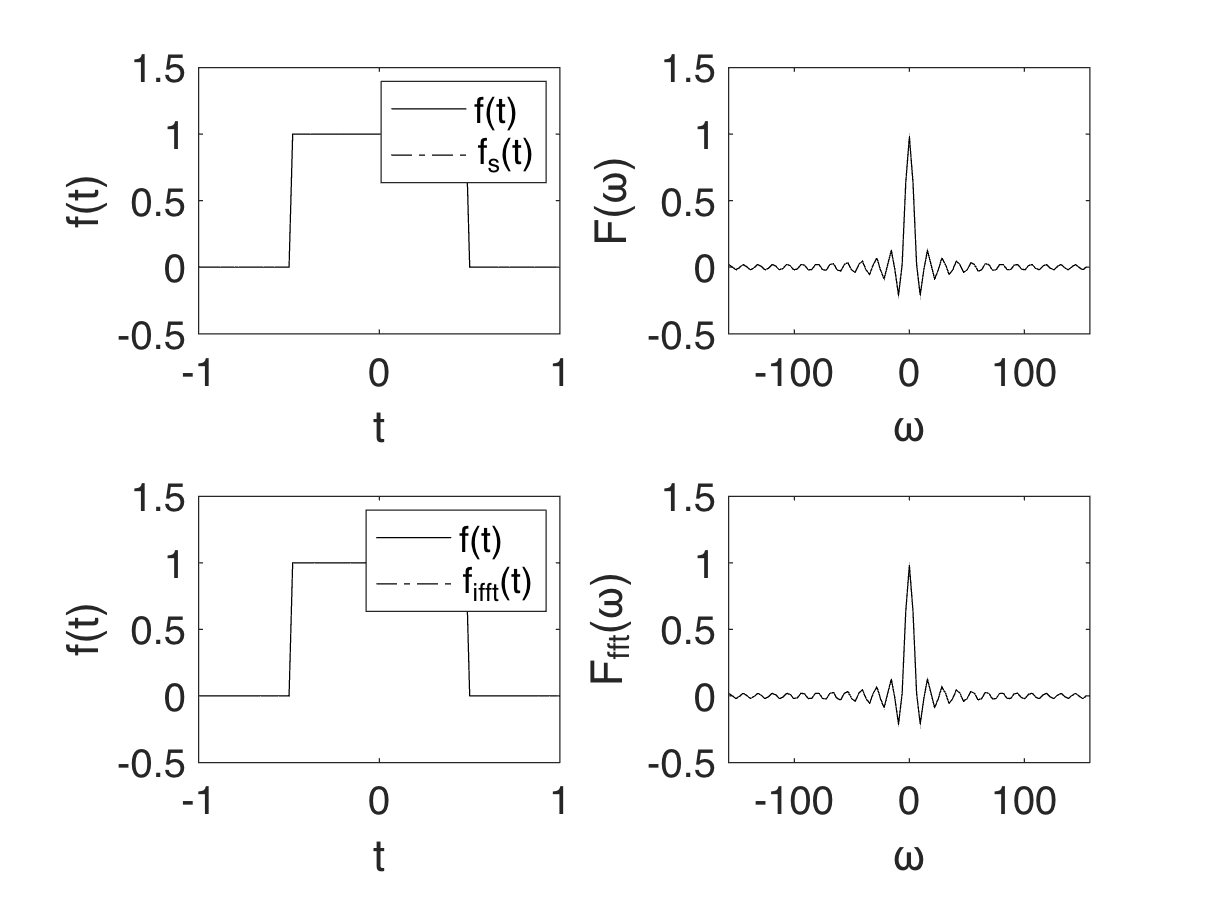

figure;

subplot(2,2,1), hold on, box on;
plot(t,f,'k-');
plot(t,fs,'k-.');
set(gca,'YLim',[-.5 1.5],'FontSize',16);
xlabel('t');
ylabel('f(t)');
legend('f(t)','f_s(t)');

subplot(2,2,2), hold on, box on;
plot(omg,real(F),'k-');
set(gca,'XLim',[-OMG/2,OMG/2],'YLim',[-0.5 1.5],'FontSize',16);
xlabel('\omega');
ylabel('F(\omega)');

subplot(2,2,3), hold on, box on;
plot(t,f,'k-');
plot(t,f_ifft,'k-.');
set(gca,'YLim',[-.5 1.5],'FontSize',16);
xlabel('t');
ylabel('f(t)');
legend('f(t)','f_{ifft}(t)');

subplot(2,2,4), hold on, box on;
plot(omg,real(F_fft),'k-');
set(gca,'XLim',[-OMG/2,OMG/2],'YLim',[-0.5 1.5],'FontSize',16);
xlabel('\omega');
ylabel('F_{fft}(\omega)');